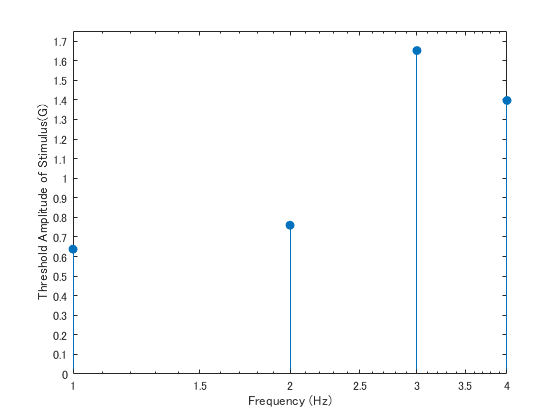

list = dir('*.csv');
numFiles = length(list);

%10列2行のセルを作成。1列目に3軸加速度（V)の行列、2列目に3軸のRMS値（g）
%（できれば1-の連番にして一々ファイル名を変更しないでも良いようにしたい
Mx = cell(10,2);        %1-10を格納

%加速度センサの感度V/gを入力
vg = 0.8;     

%グラフ出力用のセルを定義
G = cell(40,2);

for i = 1:4
    importFile = sprintf('%d.csv', i); %i.csvの名前のファイルをインポート
    Mx{i,1} = csvread(importFile,21,1,[21,1,10020,3]); %ファイル名をi.csvでインポート
    Mx{i,2} = ( rms(Mx{i,1}(:,1)) + rms(Mx{i,1}(:,2)) + rms(Mx{i,1}(:,3)) ) / vg;
    G{i,1} = i;%セルの1列目に周波数を入力
    G{i,2} = Mx{i,2};%セルの2列面に計算した加速度を入力
end

%cell配列を通常の配列に変換してgraph
graphdata = cell2mat(G);

%グラフ生成
stem(graphdata(:,1),graphdata(:,2),'filled');  %〇を埋める

%グラフの装飾
set(gca,'xscale','log');    %x軸をlogscaleに
xlabel('Frequency (Hz)');
ylabel('Threshold Amplitude of Stimulus(G)');
yticks(-0.1:0.1:max(graphdata(:,2)) + 0.1)
xlim([min(graphdata(:,1)) max(graphdata(:,1))])
ylim([0.0 max(graphdata(:,2))+0.1])